# Práctica 6

### I. Transformación del espacio de representación

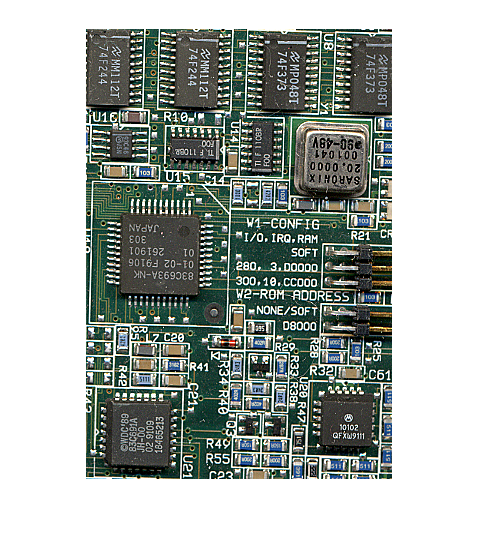

clc, clear all, close all

I = imread("Board_Recorte.tif");
imshow(I);

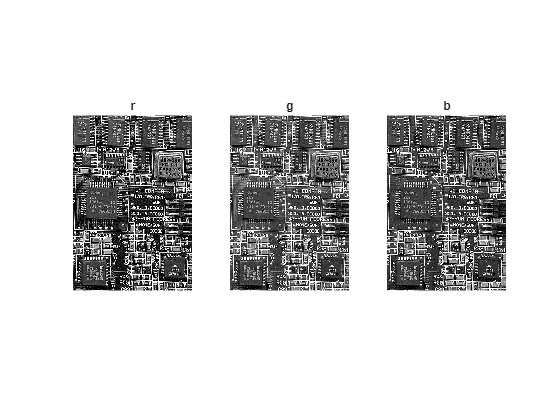


figure;
subplot(1, 3, 1), imshow(I(:,:,1)), title('r');
subplot(1, 3, 2), imshow(I(:,:,2)), title('g');
subplot(1, 3, 3), imshow(I(:,:,3)), title('b');

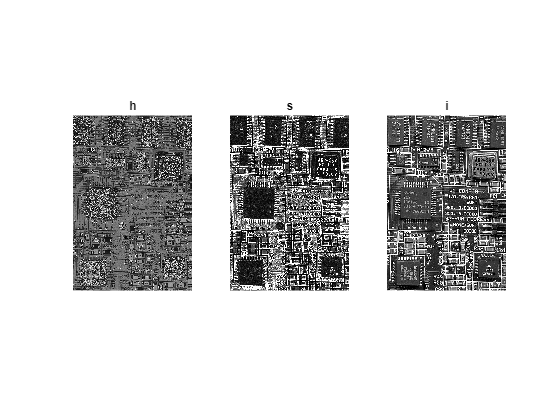


% Pasar a HSI
[I_HSI_H, I_HSI_S, I_HSI_I] = rgb2hsi(I);

Componente = I_HSI_S;

figure;
subplot(1, 3, 1), imshow(I_HSI_H), title('h');
subplot(1, 3, 2), imshow(I_HSI_S), title('s');
subplot(1, 3, 3), imshow(I_HSI_I), title('i');

### II. Umbralización y filtrado 

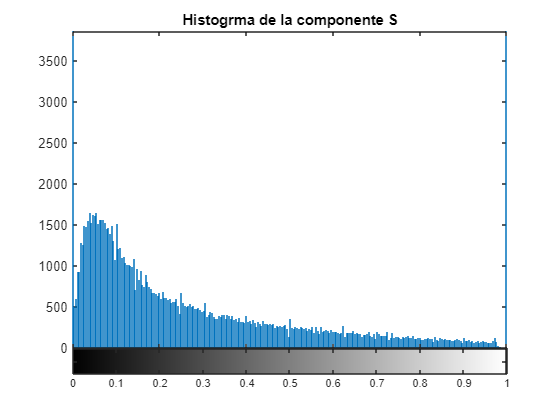

figure;
imhist(Componente), title('Histogrma de la componente S');

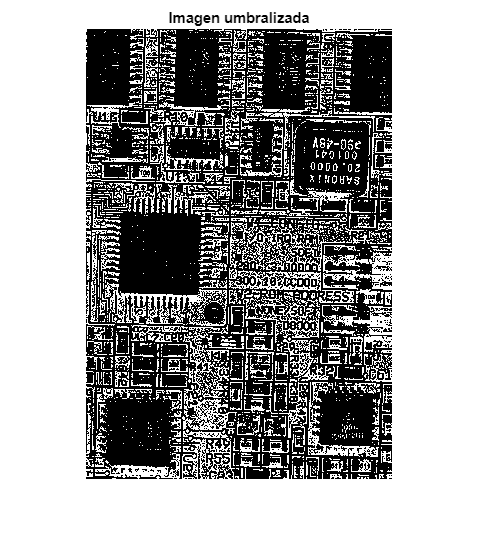


% Método de Otsu -> min(sigma^2) = w1*sigma1^2 + w2*sigma2^2 (Nos quedamos con el valor mínimo)
level = graythresh(Componente);
I_U = im2bw(Componente, level);

I_U = uint8(I_U*255);
figure;
imshow(I_U), title('Imagen umbralizada');

### III. Aplicación de operadores morfológicos

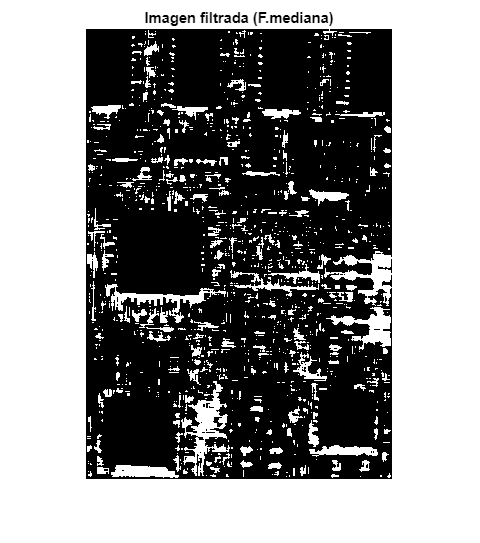

I_U_filt_comp = medfilt2(I_U,[5 5]);
figure;
imshow(I_U_filt_comp), title('Imagen filtrada (F.mediana)');

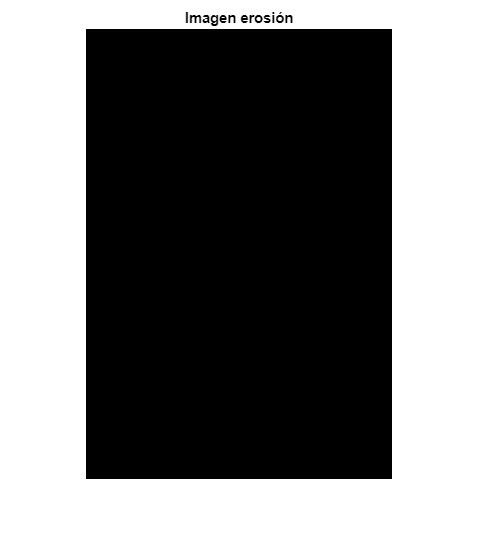


EE_cuadrado = strel('square', 35);

% Erosión
B_erode = imerode(I_U_filt_comp, EE_cuadrado);

figure;
imshow(B_erode), title('Imagen erosión');

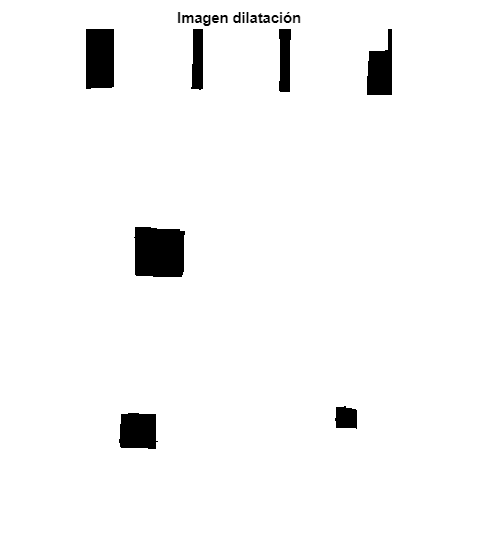


% Dilatación
B_dilate = imdilate(I_U_filt_comp, EE_cuadrado);

figure;
imshow(B_dilate), title('Imagen dilatación');

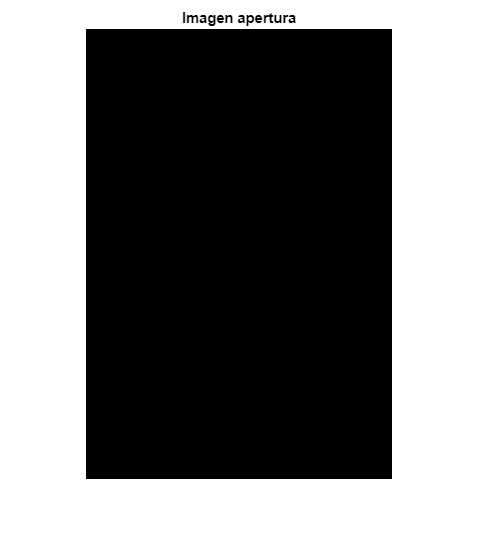


% Apertura
B_Open = imopen(I_U_filt_comp, EE_cuadrado);

figure;
imshow(B_Open), title('Imagen apertura');

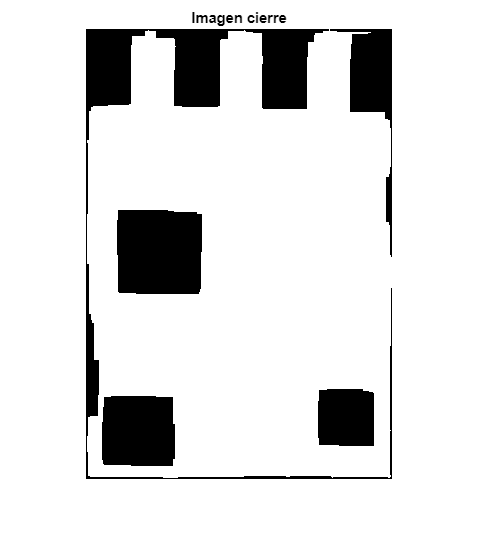


% Cierre
B_Close = imclose(I_U_filt_comp, EE_cuadrado);

figure;
imshow(B_Close), title('Imagen cierre');


% Elegimos el mejor resltado que es el cierre
Im_Res_Morf = B_Close;

### IV. Segmentación y caracterización de objetos

IM_Seg = bwlabel(Im_Res_Morf);
RGB_Segment = label2rgb(IM_Seg);

Num_objetos = max(IM_Seg(:)) 

Num_objetos = 1

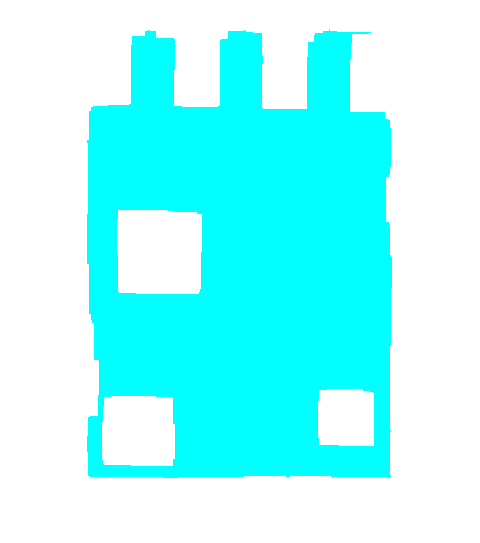


figure;
imshow(RGB_Segment);

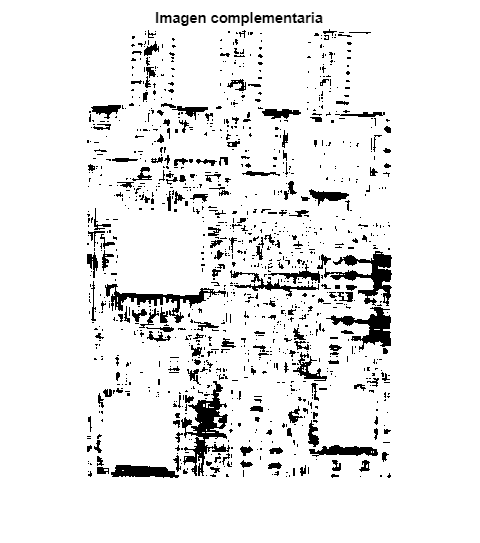


% Trabajamos con la complementaria
I_U_filt_comp = 255 - I_U_filt;

figure;
imshow(I_U_filt_comp), title('Imagen complementaria');

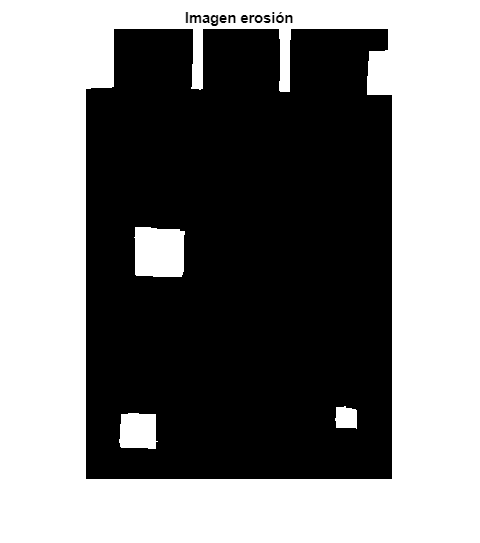


EE_cuadrado = strel('square', 35);

% Erosión
B_erode2 = imerode(I_U_filt_comp, EE_cuadrado);

figure;
imshow(B_erode2), title('Imagen erosión');

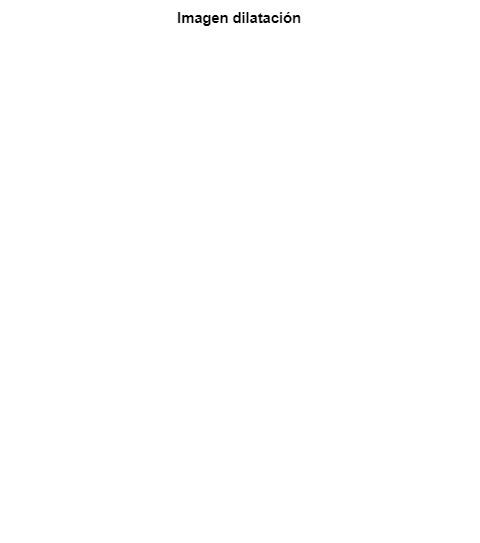


% Dilatación
B_dilate2 = imdilate(I_U_filt_comp, EE_cuadrado);

figure;
imshow(B_dilate2), title('Imagen dilatación');

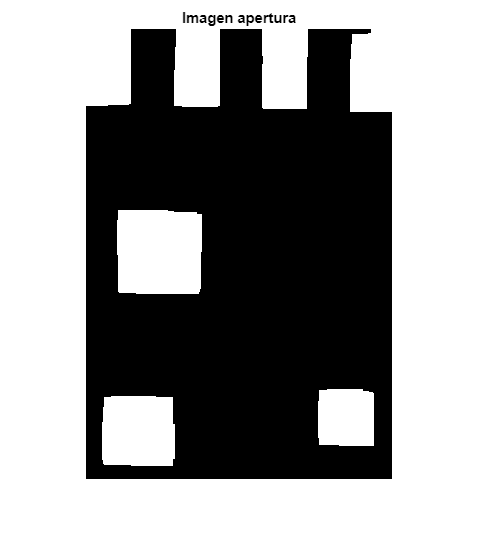


% Apertura
B_Open2 = imopen(I_U_filt_comp, EE_cuadrado);

figure;
imshow(B_Open2), title('Imagen apertura');

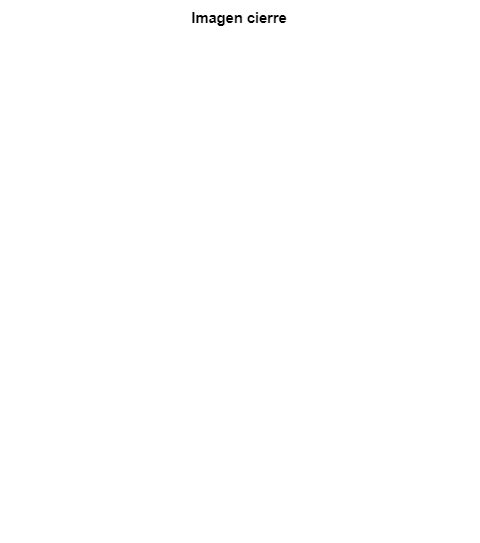


% Cierre
B_Close2 = imclose(I_U_filt_comp, EE_cuadrado);

figure;
imshow(B_Close2), title('Imagen cierre');


% Elegimos el mejor resltado que es la apertura
Im_Res_Morf2 = B_Open2;

IM_Seg2 = bwlabel(Im_Res_Morf2);
RGB_Segment = label2rgb(IM_Seg);

Num_objetos = max(IM_Seg(:));

figure;
imshow(RGB_Segment);

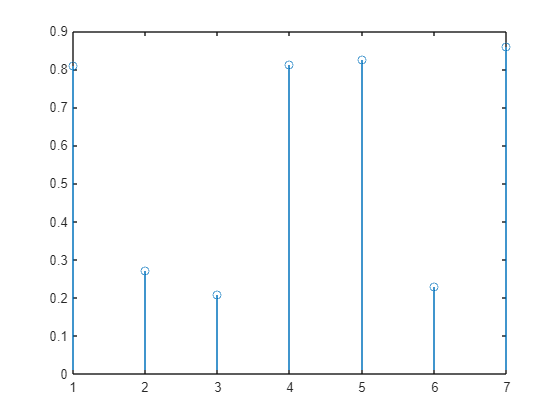


%
Props = regionprops(IM_Seg2, 'Eccentricity');
V_Excent = [];
V_Excent = [V_Excent Props(1).Eccentricity];
V_Excent = [V_Excent Props(2).Eccentricity];
V_Excent = [V_Excent Props(3).Eccentricity];
V_Excent = [V_Excent Props(4).Eccentricity];
V_Excent = [V_Excent Props(5).Eccentricity];
V_Excent = [V_Excent Props(6).Eccentricity];
V_Excent = [V_Excent Props(7).Eccentricity];

figure;
stem(V_Excent);

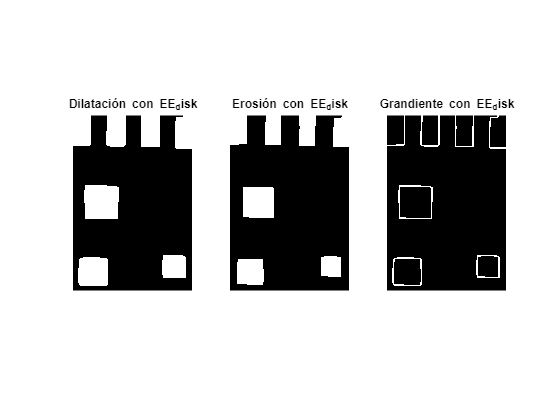


% Con otro elemento esructurante
EE_disk = strel('disk',2);
B_dilate_disk = imdilate(Im_Res_Morf2, EE_disk); % Dilatación de la imagen ya segmentada
B_erode_disk = imerode(Im_Res_Morf2, EE_disk);
B_gradiente = B_dilate_disk - B_erode_disk; % Busca los píxeles a uno que hay solo en una imagen.

figure;
subplot(1, 3, 1), imshow(B_dilate_disk), title('Dilatación con EE_disk');
subplot(1, 3, 2), imshow(B_erode_disk), title('Erosión con EE_disk');
subplot(1, 3, 3), imshow(B_gradiente), title('Grandiente con EE_disk');

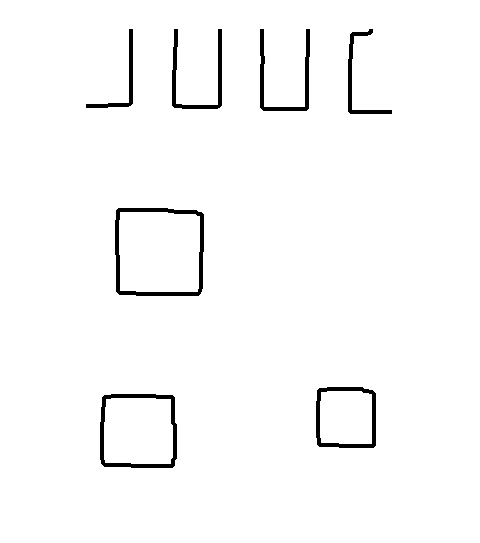


%
Neg_Bgrad = 1- B_gradiente;

figure;
imshow(Neg_Bgrad, [])

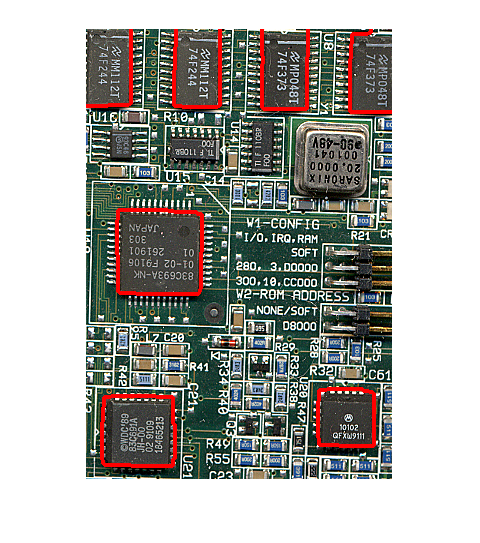


I_2 = I;
I_2(:,:,1) = I(:,:,1).*uint8(Neg_Bgrad);
I_2(:,:,2) = I(:,:,2).*uint8(Neg_Bgrad);
I_2(:,:,3) = I(:,:,3).*uint8(Neg_Bgrad);

Frontera(:,:,1) = B_gradiente;
Frontera(:,:,2) = zeros(size(B_gradiente));
Frontera(:,:,3) = zeros(size(B_gradiente));

FINAL = imadd(uint8(255*Frontera), I_2);

figure;
imshow(FINAL, []);